path = dir("G:\My Drive\1. Projects\PHYS-559 Graduate Laboratory (Spring 2023)\NMR Project\Final Paper Data\0.3059M\*.csv")

path = 24×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


sampleConcentration = '0.3059M'

sampleConcentration = '0.3059M'

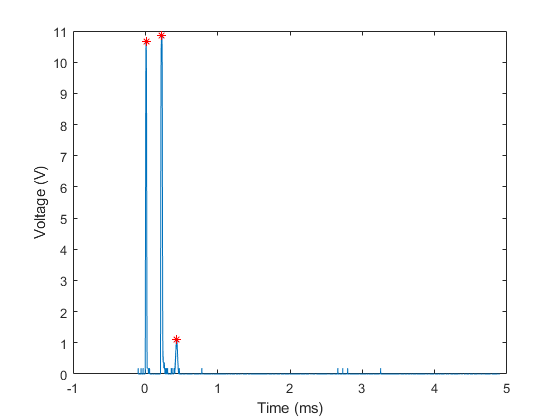

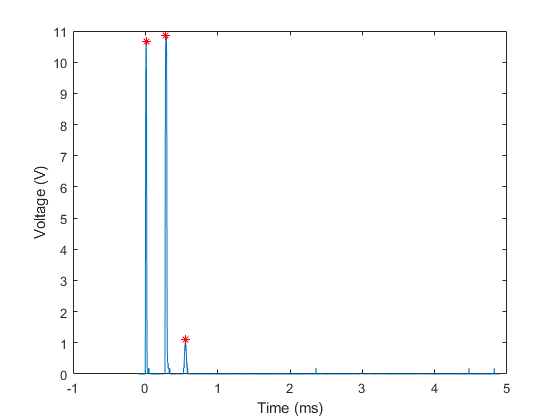

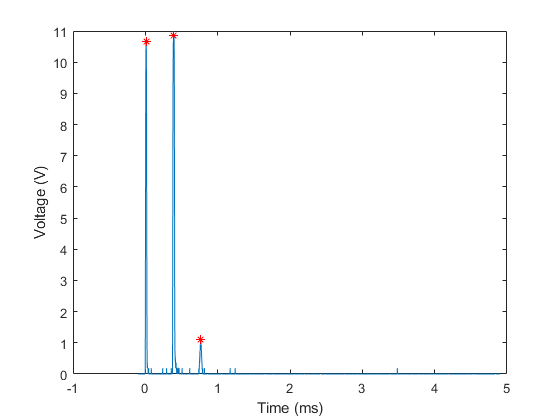

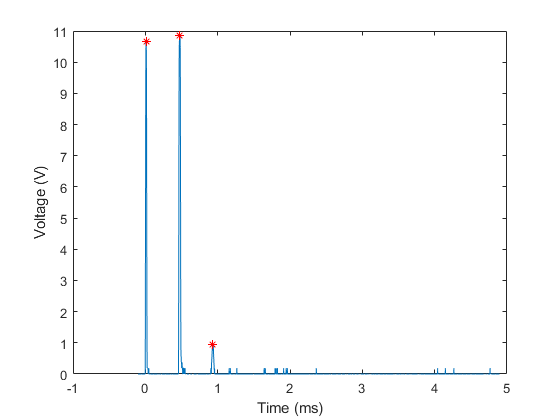

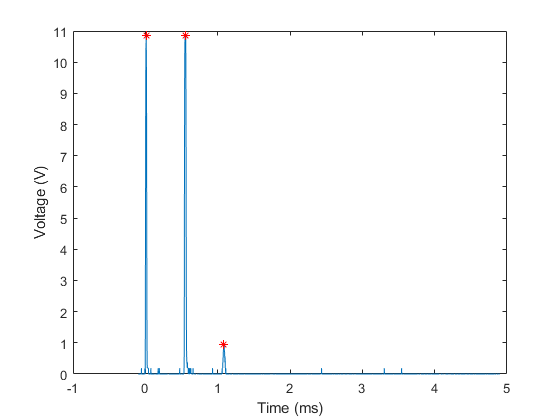

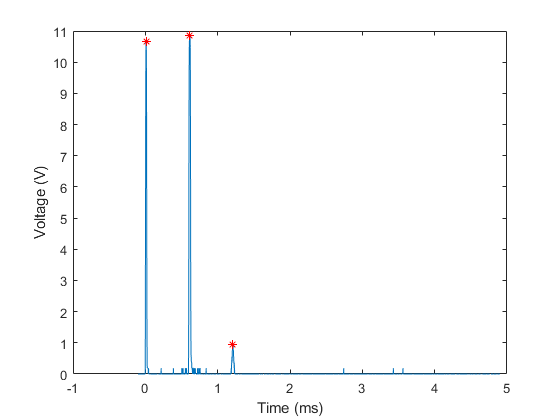

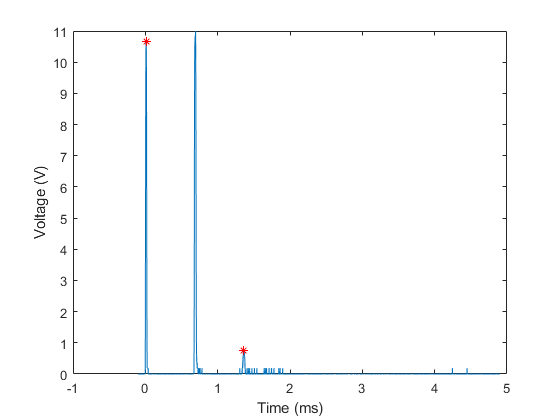

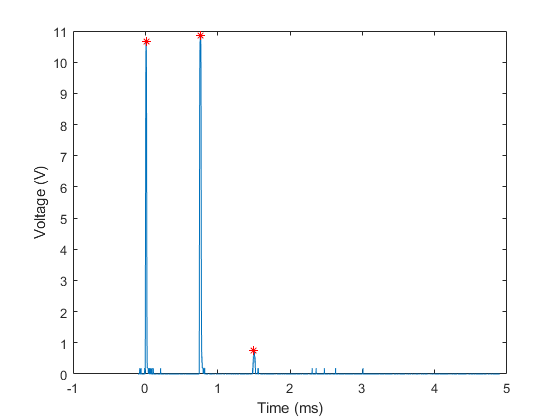

pulse_seperation =          0    0.2133         0    0.2748         0    0.3805         0    0.4647         0    0.5387         0    0.6032    0.6844         0    0.7503         0    0.8215         0    0.9041    1.0035    1.0821    1.1849    1.2761    1.3467


spinEchoAmp =          0    1.1220         0    1.1220         0    1.1220         0    0.9350         0    0.9350         0    0.9350    0.7480         0    0.7480         0    0.7480         0    0.7480    0.5610    0.5610    0.5610    0.3740    0.3740


[pulse_seperation, spinEchoAmp] = NMRdataAnalysis(path,sampleConcentration)

logSpinEchoAmp = log(spinEchoAmp)

logSpinEchoAmp =       -Inf    0.1152      -Inf    0.1152      -Inf    0.1152      -Inf   -0.0672      -Inf   -0.0672      -Inf   -0.0672   -0.2903      -Inf   -0.2903      -Inf   -0.2903      -Inf   -0.2903   -0.5780   -0.5780   -0.5780   -0.9835   -0.9835


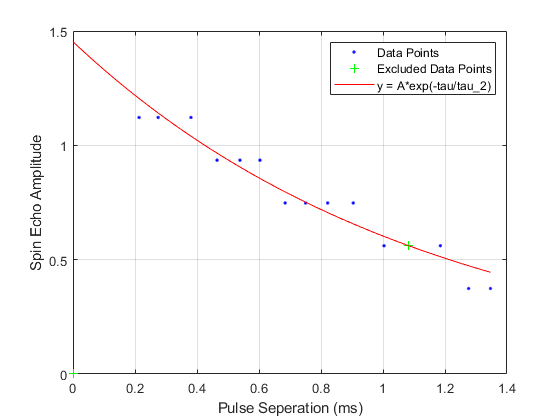

fitresult =      General model:
     fitresult(t) = A*exp(-t/t_2)
     Coefficients (with 95% confidence bounds):
       A =       1.453  (1.308, 1.598)
       t_2 =       1.138  (0.9338, 1.342)

gof = struct with fields:
           sse: 0.0535
       rsquare: 0.9372
           dfe: 12
    adjrsquare: 0.9320
          rmse: 0.0668


[fitresult, gof] = exponentialFit(pulse_seperation, spinEchoAmp)

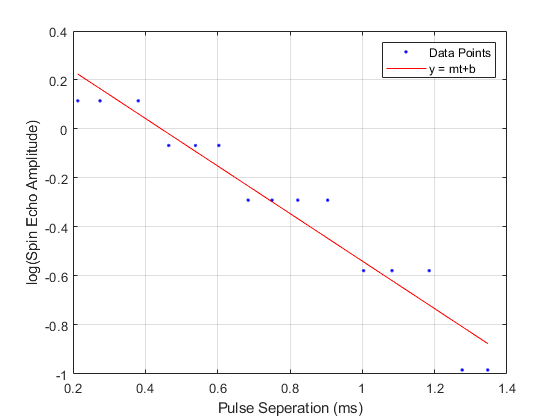

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
       where x is normalized by mean 0.7686 and std 0.3608
     Coefficients (with 95% confidence bounds):
       p1 =     -0.3502  (-0.4071, -0.2933)
       p2 =     -0.3145  (-0.3695, -0.2596)

gof = struct with fields:
           sse: 0.1263
       rsquare: 0.9315
           dfe: 13
    adjrsquare: 0.9262
          rmse: 0.0986


[fitresult, gof] = linearFit(pulse_seperation, logSpinEchoAmp)

function [fitresult, gof] = exponentialFit(pulse_seperation, spinEchoAmp)
%CREATEFIT(PULSE_SEPERATION,SPINECHOAMP)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : pulse_seperation
%      Y Output: spinEchoAmp
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Feb-2023 23:29:50


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( pulse_seperation, spinEchoAmp );

% Set up fittype and options.
ft = fittype( 'A*exp(-t/t_2)', 'independent', 't', 'dependent', 'y' );
excludedManually = excludedata( xData, yData, 'Indices', 21 );
excludedByRule = (yData < 0.2) | (yData > 2);
excludedPoints = excludedManually | excludedByRule;
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.186872604554379 0.489764395788231];
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData, excludedPoints );
legend( h, 'Data Points', 'Excluded Data Points', 'y = A*exp(-tau/tau_2)', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Pulse Seperation (ms)', 'Interpreter', 'none' );
ylabel( 'Spin Echo Amplitude', 'Interpreter', 'none' );
grid on


end
function [fitresult, gof] = linearFit(pulse_seperation, logSpinEchoAmp)
%CREATEFIT1(PULSE_SEPERATION,LOGSPINECHOAMP)
%  Create a fit.
%
%  Data for 'Linear Fit' fit:
%      X Input : pulse_seperation
%      Y Output: logSpinEchoAmp
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Feb-2023 22:39:47


%% Fit: 'Linear Fit'.
[xData, yData] = prepareCurveData( pulse_seperation, logSpinEchoAmp );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, 'Normalize', 'on' );

% Plot fit with data.
figure( 'Name', 'Linear Fit' );
h = plot( fitresult, xData, yData );
legend( h, 'Data Points', 'y = mt+b', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Pulse Seperation (ms)', 'Interpreter', 'none' );
ylabel( 'log(Spin Echo Amplitude)', 'Interpreter', 'none' );
grid on
end

